clc
clear
RGB = readmatrix('thickness_all\thickness2rgb.csv');
t = RGB(:,1);
r_v = RGB(:,2)/256;
g_v = RGB(:,2)/256;
b_v = RGB(:,3)/256;
xyz_v = rgb2xyz([r_v,g_v,b_v]);

x = 1000;       %薄膜厚度/nm
n = 1.428;      %薄膜折射率
n0 = 1;         %空气折射率
ng = 3.836;     %硅片折射率
i = 0;          %折射角
lambda = 360:830;
x = 1:x;
delta = 4*pi*n*x'*cos(i)./lambda;
R = (n^2*(n0-ng)^2*cos(delta/2).^2+(n^2-n0*ng)^2*sin(delta/2).^2)./...
       (n^2*(n0+ng)^2*cos(delta/2).^2+(n^2+n0*ng)^2*sin(delta/2).^2);
cie = colorMatchFcn('1931_full');
XYZ = R*cie(:,2:4);
xyz_norm = normalize(XYZ,2,'norm',1);
rgb = xyz2rgb(xyz_norm);

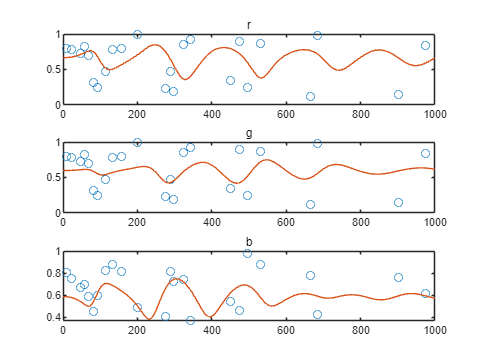

subplot(3,1,1)
plot(t,r_v,'o')
title('r')
hold on
plot(rgb(:,1))
hold off
subplot(3,1,2)
plot(t,g_v,'o')
title('g')
hold on
plot(rgb(:,2))
hold off
subplot(3,1,3)
plot(t,b_v,'o')
title('b')
hold on
plot(rgb(:,3))
hold off

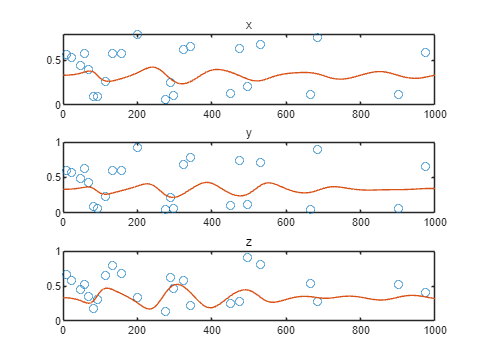

subplot(3,1,1)
plot(t,xyz_v(:,1),'o')
title('x')
hold on
plot(xyz_norm(:,1))
hold off
subplot(3,1,2)
plot(t,xyz_v(:,2),'o')
title('y')
hold on
plot(xyz_norm(:,2))
hold off
subplot(3,1,3)
plot(t,xyz_v(:,3),'o')
title('z')
hold on
plot(xyz_norm(:,3))
hold off

res_x = @(x) R.*(x(1)+x(2)*cie(:,1)+x(3)*cie(:,1).^2)'*cie(:,2);
f = @(x)model_x(x, cie, R, t, xyz_v(:,1))

f = 包含以下值的 function_handle :
    @(x)model_x(x,cie,R,t,xyz_v(:,1))


x0 = [0 0 0];
[x,fval] = fminunc(f,x0)


Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


x = 1.0e-07 *

    0.0000    0.0012    0.5733


fval = 1.3780

function res = model_x(x, cie, R, t, x_v)
    x_t = R.*(x(1)+x(2)*cie(:,1)+x(3)*cie(:,1).^2)'*cie(:,2);
    res = sum((x_t(t)-x_v).^2);
end